
% figure R vs Direction %

clear all;
close all;

load('E:\Data\2024-11-22\BxByScan.mat');
clear Bx;
clear By;



conversionx = 10/4*108/115;
conversiony = 10/4*108/82;

Bx = BxBy(:,1)*conversionx;   % mGauss
By = BxBy(:,2)*conversiony;   % mGauss

weight = 1./err.^2;


ratio_mean = sum(ratio.*weight,2)./sum(weight,2);
err_mean = sqrt(sum(weight.* ((ratio-ratio_mean).^2 + 1./weight),2) ./ sum(weight,2));


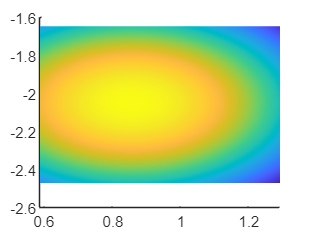


%% 拟合: '无标题拟合 1'。
w = 1./err_mean.^2;
[xData, yData, zData, weights] = prepareSurfaceData(Bx, By, ratio_mean, w);

% 设置 fittype 和选项。
ft1 = fittype( 'a1*(x-c1)^2+a2*(y-c2)^2+d',...
    'independent', {'x', 'y'}, 'dependent', 'z' );
opts1 = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts1.Display = 'Off';
opts1.Lower = [-5/conversionx^2 -5/conversiony^2 -1*conversionx -1.5*conversiony 0.725];
opts1.Upper = [1/conversionx^2 1/conversiony^2 1*conversionx 1*conversiony 0.727];
opts1.StartPoint = [-2e-7 -4e-7 0.2*conversionx -0.3*conversiony 0.726];
opts1.Weights = weights;

% 对数据进行模型拟合。
[fitresult, gof1] = fit( [xData, yData], zData, ft1, opts1 );
a1 = fitresult.a1;
a2 = fitresult.a2;
c1 = fitresult.c1;
c2 = fitresult.c2;
R_min = fitresult.d;

interval = confint(fitresult);
a1_sigma = (interval(2,1)-interval(1,1))/4;
a2_sigma = (interval(2,2)-interval(1,2))/4;
c1_sigma = (interval(2,3)-interval(1,3))/4;
c2_sigma = (interval(2,4)-interval(1,4))/4;
R_sigma = (interval(2,5)-interval(1,5))/4;


% 计算 Chi square %
chi_square1 = 0;
for k1 = 1:length(ratio_mean)
    temp1(k1) = (ratio_mean(k1)-fitresult(Bx(k1),By(k1)))^2;
    chi_square1 = chi_square1 + w(k1)*temp1(k1);
end
chi_square1 = chi_square1/(length(ratio_mean)-5);


f1 = figure; %hold on;

Bx_low = min(Bx)*1;
Bx_high = max(Bx)*1;
By_low = min(By)*1;
By_high = max(By)*1;

[Bx_surf,By_surf] = meshgrid(Bx_low:(Bx_high-Bx_low)/100:Bx_high,...
    By_low:(By_high-By_low)/100:By_high);

ratio_surf = fitresult(Bx_surf,By_surf);

as1 = axes('Parent',f1);
hold(as1,'on');

%s1 = plot( fitresult);%, ratio_mean );
s1 = surf(Bx_surf,By_surf,ratio_surf,'Parent',as1);
shading interp;

alpha(s1,1);
cMap=getPyPlot_cMap('Oranges',128,0,"C:\Users\USTC\AppData\Local\Programs\Python\Python313\python");

函数或变量 'getPyPlot_cMap' 无法识别。

colormap(cMap);
clim([0.726013 0.72612]);

%s1(2).MarkerEdgeColor = [0.7 0 0];
%s1(2).MarkerFaceColor = [1 0.6 0.5];
%'Color',[0.5 0.4 0.3]
%s1(2).LineWidth = 2;

xlim([0.5 1.5]);
ylim([-2.5 -1.5]);

%daspect auto;

%% 绘制原始数据 %%

E1 = plot3(Bx, By, ratio_mean,'o','markersize',6,'LineWidth',2,...
    'MarkerEdgeColor',[0.82 0.45 0.0],'MarkerFaceColor',[0.98 0.73 0.48],...
    'Parent',as1);

for k = 1:length(ratio_mean)
    plot3([Bx(k),Bx(k)], [By(k),By(k)],[-err_mean(k),err_mean(k)]+ratio_mean(k),...
        '-','Color',[0.79 0.4 0.0],'LineWidth',1.6,'Parent',as1);
end

%title('R vs Transverse B','FontName','Arial','FontWeight','bold');
xlabel('B_x mGauss','Rotation',-41,'Position',[1.16563,-2.55541,0.72591]);
ylabel('B_y mGauss','Rotation',13,'Position',[1.52943,-2.11854,0.72592]);
zlabel('R_L');

view(as1,[62.52178 36.37076]);
hold(as1,'off');

set(gca,'FontName','Times New Roman','FontSize',16,'FontWeight','bold');

% legend('',['R_{min} = ',num2str(roundn(R_min,-6),'%.6f'),'(',num2str(round(R_sigma*1e6)),')', ...
%     newline '\chi^2_{reduced} = ',num2str(roundn(chi_square1,-2),'%.2f')], ...
%     'Location','best','FontSize',14);

legend('',['R_{L,min} = ',num2str(roundn(R_min,-6),'%.6f'),'(',num2str(round(R_sigma*1e6)),')'], ...
    'Position',[0.26244 0.82308 0.38214 0.08095],'FontSize',14);


set(f1,'Visible','on');



% savefig(f1,'E:\Comagnetometer_Pub\RvsDirection\RvsD100.fig');
% saveas(f1,'E:\Comagnetometer_Pub\RvsDirection\RvsD100.png');
% saveas(f1,'E:\Comagnetometer_Pub\RvsDirection\RvsD100.eps','psc');
% saveas(f1,'E:\Comagnetometer_Pub\RvsDirection\RvsD100.svg');
% 
% save('E:\Comagnetometer_Pub\RvsDirection\RvsD100.mat');
